**1.) El primer que farem és llegir les imatges i les convertim a *****double*****.**

A = double(imread('_MG_7735.JPG'))/255;
B = double(imread('_MG_7737.JPG'))/255;

**2.) Comprovem que passaria si superposem les imatges directament. Per veure-ho, restem les imatges píxel a píxel i el resultat el re-escalem entre 0-1. **

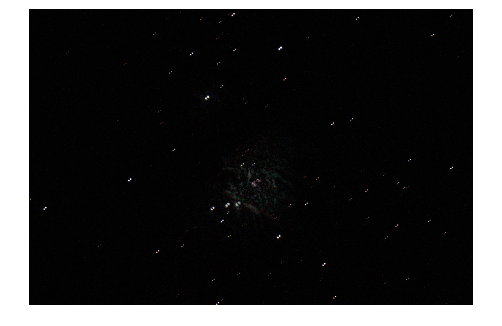

DIF = abs(A-B); % imatge diferencia
maxim = max(DIF(:));
DIF = DIF/maxim; % dividim pel seu valor màxim
imshow(DIF);

S’observa en la imatge diferència que les imatges apareixen mogudes una respecte a l’altre. Això és degut a la rotació terrestre i a que les imatges han estat preses en instants de temps diferents.  Entre una imatge i l’altre han transcorregut alguns minuts i en conseqüència les imatges apareixen desplaçades aproximadament 20 píxels en horitzontal i 20 píxels en vertical.

3.) **Traslladem per codi la imatge B 20 píxels en diagonal i observem que les imatges s’ajusten  prou bé. ***Nota: Aquest desplaçament d’una imatge sobre l’altre es pot fer automàticament i en temes  posteriors es veurà com fer-ho. Penseu que utilitzant centenars d’imatges obtindríem una imatge molt  millorada pel que fa a l’exposició (captació de llum). *

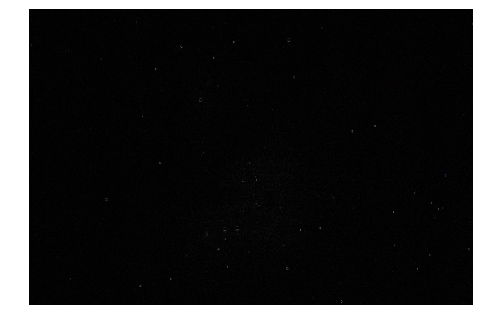

Bd = imtranslate(B,[20, -20]); 
DIF = abs(A-Bd); 
maxim = max(DIF(:));
DIF = DIF/maxim; 
imshow(DIF);

*Aqui podem veure que la imatge diferencia es gairebe tota negre (0), el que ens indica que les dues imatges estan bastant alineades*

**4.) Ara ja podem sumar les dues imatge A i Bd per obtenir una nova imatge integrada o  sumatori amb més “senyal”**

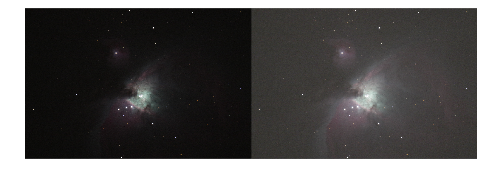

Am = (A+Bd)/2; % imatge sumatori amb més senyal que A i B 
Ac = arrayfun(@(x) sqrt(x), Am);
 % poseu aquí les línies de codi que facin falta per contrastar la imatge 
montage ({A,Ac}); 

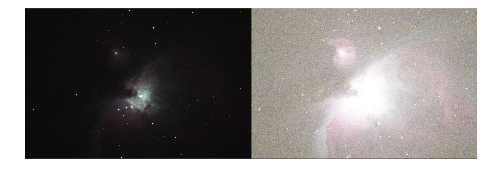


Ac = arrayfun(@(x) 1-exp(-20*x), Am);
%% aquesta es una de les que vam fer servir a classe
montage ({A,Ac}); 

*Aqui hem probat amb algunes funcions,pero no hem arribat a cap amb un nivell de detall gaire alt, totes ens han sortit amb massa brillantor.*

**HSV**

*Hem fet servir el HSV , tot i així també podríem extreure un resultat paregut utilitzant el mètode trobat a l’enllaç adjuntat a la pràctica per tal d’utilitzar HSL. Aquestes funcions de la pàgina web donen bon resultat per ressaltar els detalls de la nebulosa ja que podem jugar amb les components de saturació i lluminositat per ajustar aquesta. Finalment ens hem quedat amb l'HSV ja que ens sembla que el resultat ha sigut prou bó.*

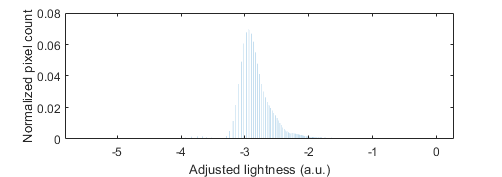

Am = (A+Bd)/2; % imatge millorada
[H,S,V] = rgb2hsv(Am);
LOGO = log(V);
histogram(LOGO,'Normalization','probability','EdgeColor','none');
xlabel('Adjusted lightness (a.u.)')
ylabel('Normalized pixel count')



LOGO = rescale(LOGO,"InputMin",-3);
HSV= hsv2rgb(H,S*1.5,LOGO);
montage ({A,HSV});

*Aqui hem anat jugant amb el valor de InputMin, primerament l'haviem posat a -4 però els negres es tornaven una barreja de pixels vermells, blaus y verds. Hem anat pujant en intervals de 0.1 fins arribar a -3, on els negres són bastant foscos però els altres colors estan molt més resaltats.*

**LOCAL BRIGHTEN**

ALBright = imlocalbrighten(Am,0.7);
AL1 = imadjust(ALBright,[.1 .1 .1; 1 1 1],[]);
montage ({A,AL1});

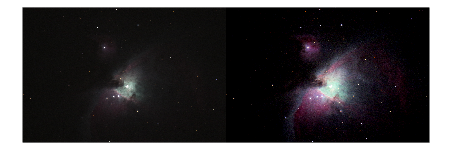


AL2 = imadjust(ALBright,[.2 .2 .2; 1 1 1],[]);
montage ({A,AL2});


AL3 = imadjust(ALBright,[.5 .5 .5; 1 1 1],[]);
montage ({A,AL3});

*Amb el imlocalbrighten donem mes llum a tota la imatge en general, pro dons els negres queden grisos. Amb el imadjust ajustem el que es considera negre i el que es considera blanc en els parametres; podem veure com a mesura que anem pujant el que valor del negre la imatge es va tornant més fosca.*

**Finalment amb la combinació de imlocalbrightness i imadjust amb els foscos a 0.2 podem veure clarament les estrelles majors en un color vermellós; però en el HSV es poden observerar alguns petits puntets blancs que no sabem si són o no estrelles.**

** En el cas de que ho fossin, el millor processat seria el HSV; i en cas contrari el AL2.**